load iris.mat


type = 'classification';
gam = 1;
t = 1;
degree = 5;

kpar = [t ; degree];

% sig2 = 0.2;

kernel_type = 'poly_kernel'

kernel_type = 'poly_kernel'


% Find the support values and the bias term of a
% Least Squares Support Vector Machine

[alpha,b] = trainlssvm({Xtrain,Ytrain,type,gam,kpar,kernel_type});

% Evaluate the LS-SVM at the given points

Ypred = simlssvm({Xtrain,Ytrain,type,gam,kpar,kernel_type,'preprocess'},{alpha,b},Xtest);


eval = Evaluate(Ytest,Ypred);
disp('accuracy');

accuracy


disp(eval(1));

     1



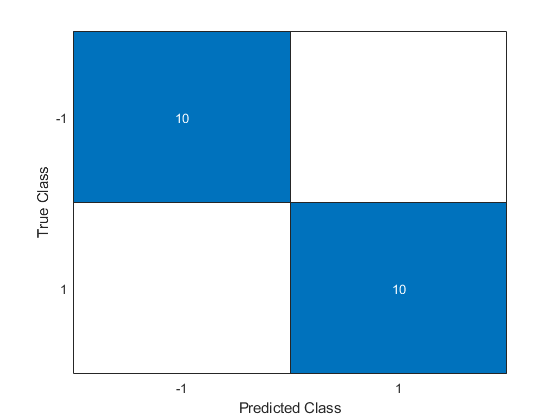

C =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties



% plotconfusion(Ytest',Ypred')
C = confusionchart(Ytest,Ypred)

Start Plotting...

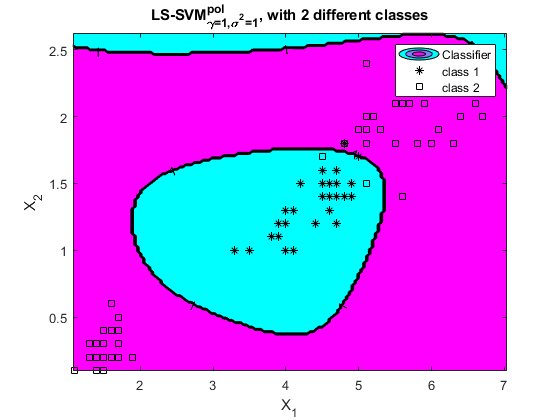

finished


% plot the LS-SVM results in the environment of the training data 

plotlssvm({Xtrain,Ytrain,type,gam,kpar,kernel_type,'preprocess'},{alpha,b});